Visualize the map

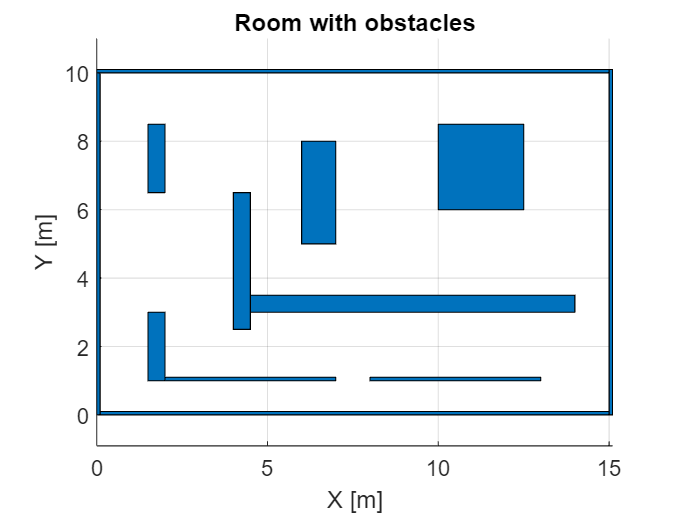

    select_map = 2;
switch select_map
    case 1
        %Map 1
        % Define max map dimensions
        x_map_size = 10;
        y_map_size = 10;
        obstacles = [0, 0, 10, 0.1;     %
                     0, 0, 0.1, 10;     % these are the walls
                     10, 0, 0.1, 10.1;  %
                     0, 10, 10, 0.1;    %
                     2.3, 1.5, 0.1, 3;
                     2.3, 4.5, 2, 0.1;
                     4.3, 4.5, 0.1, 1.7;
                     1.4, 6.2, 3, 0.1;
                     1.4, 6.3, 0.1, 2.4;
                     4, 1.5, 4.5, 0.1;
                     5.2, 3, 2.8, 0.1;
                     5, 8.5, 3, 0.1;
                     7.9, 4, 0.1, 4.5;
                     6, 4, 0.1, 3;];    % [x, y, width, higth]
    case 2
        % Map 2
        % Define max map dimensions
        x_map_size = 15;
        y_map_size = 10;
        obstacles = [0, 0, 15, 0.1;     %
                     0, 0, 0.1, 10;     % these are the walls
                     15, 0, 0.1, 10.1;  %
                     0, 10, 15, 0.1;    %
                     4, 3, 10, 0.5;
                     4, 2.5, 0.5, 4;
                     10, 6, 2.5, 2.5;
                     1.5, 1, 0.5, 2;
                     1.5, 6.5, 0.5, 2;
                     2, 1, 5, 0.1;
                     8, 1, 5, 0.1;
                     6, 5, 1, 3;];    % [x, y, width, higth]
    case 3
        % Map 3 
        % Define max map dimensions
        x_map_size = 10;
        y_map_size = 10;
        obstacles = [0, 0, 10, 0.1;     %
                     0, 0, 0.1, 10;     % these are the walls
                     10, 0, 0.1, 10.1;  %
                     0, 10, 10, 0.1;    %
                     2, 2, 6, 0.5;
                     2, 5, 0.5, 2;
                     7.5, 5, 0.5, 2;
                     5, 3.5, 0.5, 4;
                     1, 8.5, 3, 0.5;
                     6, 8.5, 3, 0.5;];    % [x, y, width, higth]
    case 4
        % Write here your own map
        % .......
end


% Iinflation factor applied to the obstacles
inflate = 0.2;
inflated_obstacles = zeros(size(obstacles));
for i = 1:height(obstacles)
    inflated_obstacles(i, 1) = obstacles(i, 1) - inflate; % x iniziale spostato a sinistra
    inflated_obstacles(i, 2) = obstacles(i, 2) - inflate; % y iniziale spostato in basso
    inflated_obstacles(i, 3) = obstacles(i, 3) + 2*inflate; % larghezza aumentata
    inflated_obstacles(i, 4) = obstacles(i, 4) + 2*inflate; % altezza aumentata
end

% Map 2
% ...

%Plot
figure();
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');

title('Room with obstacles');
PLOT_MAP_LITE(obstacles);